clear all;
close all ;
clc;
base_dir="..\data\";
cd(base_dir);

**Loading Mocap Keypoints**

! Change filenames based on current selection

mocap_all_keypoints= readtable('mocap_p1s1_noheaders.csv');

%op_raw_all_keypoints=readtable('keypoints_colab_fixed2.csv');
op_all_keypoints=readtable('keypoints_colab_fixed2.csv');

%op_kf_all_keypoints=readtable('keypoints_colab_fixed2.csv');

%selecting 1 keypoint only: LHEE
mocap_keypoint= [mocap_all_keypoints.LHEE_x mocap_all_keypoints.LHEE_y mocap_all_keypoints.LHEE_z]

mocap_keypoint = 	1.0e+03 *

   -0.0495    2.7500    0.0151
   -0.0492    2.7502    0.0149
   -0.0488    2.7502    0.0149
   -0.0484    2.7502    0.0154
   -0.0483    2.7495    0.0173
   -0.0486    2.7477    0.0228
   -0.0491    2.7424    0.0369
   -0.0492    2.7279    0.0652
   -0.0544    2.7046    0.1042
   -0.0643    2.6711    0.1343


length(mocap_keypoint)

ans = 135


n=50

n = 50

op_keypoint= [op_all_keypoints.l_heel_x(n)*960 op_all_keypoints.l_heel_y(n)*540];
first_keypoint = transpose([mocap_keypoint(n,1) mocap_keypoint(n,2) mocap_keypoint(n,3)])

first_keypoint =  -138.1030
  444.8540
   16.6655


first_keypoint_op = transpose([mocap_keypoint(n,1) mocap_keypoint(n,2) mocap_keypoint(n,3)]);
params = readstruct('c1.xml')

params = struct with fields:
    nameAttribute: "c1"
         Geometry: [1×1 struct]
        Intrinsic: [1×1 struct]
        Extrinsic: [1×1 struct]


params.Extrinsic

ans = struct with fields:
    txAttribute: 21.1943
    tyAttribute: 613.8730
    tzAttribute: 3.3935e+03
    rxAttribute: 3.1319
    ryAttribute: 1.3530
    rzAttribute: 1.5652


#### TSAI Calibration

**STEP 1: Object World Coordinate System ---> 3D coordinate system**

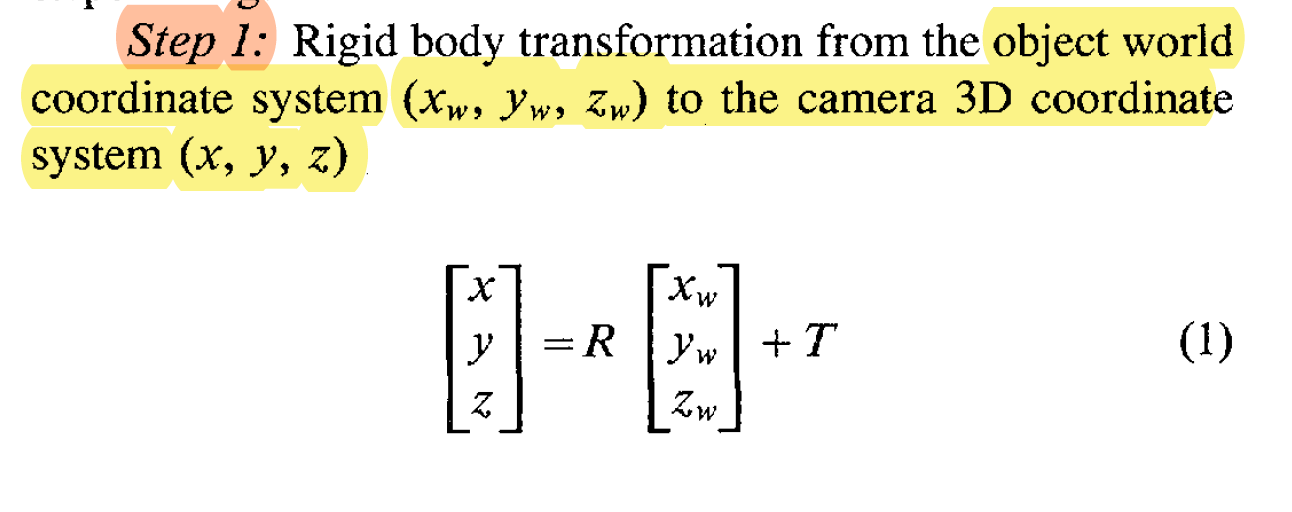 

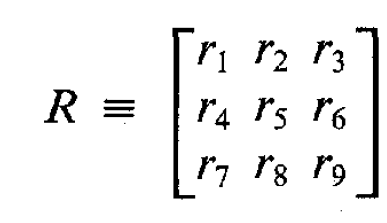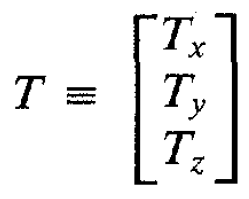

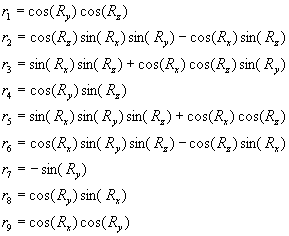

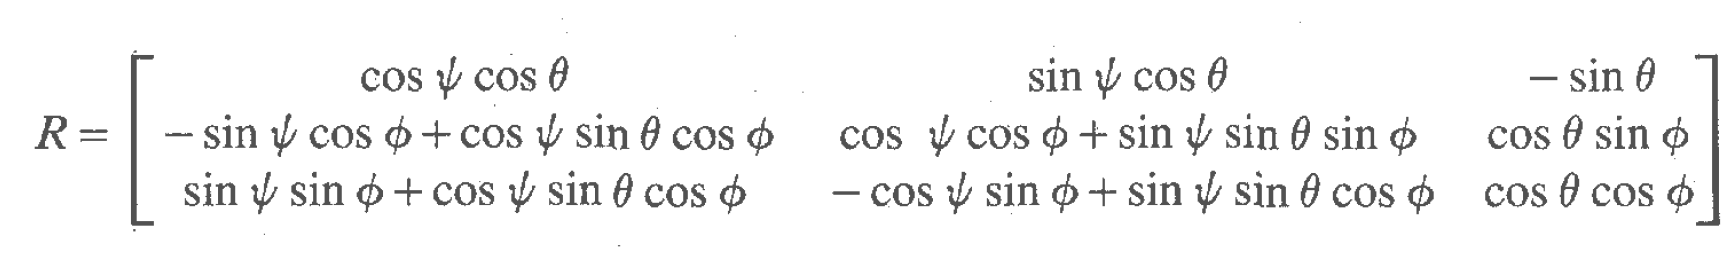

**x =**$\phi =\textrm{pitch}\;$

**y =**$\theta =\textrm{yaw}$

**z = **$\psi =\textrm{tilt}$

*Rotation matrix is still unsure*

- *euler angles*

- *different rs*

%Translation Matrix
T=transpose([params.Extrinsic.txAttribute params.Extrinsic.tyAttribute params.Extrinsic.tzAttribute])

T = 	1.0e+03 *

    0.0212
    0.6139
    3.3935



%Euler Angles
rx= params.Extrinsic.rxAttribute

rx = 3.1319

ry=params.Extrinsic.ryAttribute

ry = 1.3530

rz=params.Extrinsic.rzAttribute

rz = 1.5652



% %Rotation Matrix Elements
% r1=cos(rz)*cos(ry);
% r2=sin(rz)*cos(ry);
% r3=-sin(ry);
% r4=-(sin(rz)*cos(rx))+cos(rz)*sin(ry)*cos(rx)
% r5=cos(rz)*cos(rx)+sin(rz)*sin(ry)*sin(rx);
% r6=cos(ry)*sin(rx);
% r7= sin(rz)*sin(rx) + cos(rz)*sin(ry)*cos(rx);
% r8= -(cos(rz)*sin(rx))+sin(rz)*sin(ry)*cos(rx);
% r9=cos(ry)*cos(rx);




r1=cos(ry)*cos(rz);
r2=cos(rz)*sin(rx)*sin(ry)-cos(rx)*sin(rz);
r3=sin(rx)*sin(rz) + cos(rx)*cos(rz)*sin(ry);
r4=cos(ry)*sin(rz);
r5=sin(rx)*sin(ry)*sin(rz) + cos(rx)*cos(rz);
r6=cos(rx)*sin(ry)*sin(rz)-cos(rz)*sin(rx);
r7=-sin(ry);
r8=cos(ry)*sin(rx);
r9=cos(rx)*cos(ry);

%Rotation Matrix
R = [r1 r2 r3;
    r4 r5 r6;
    r7 r8 r9]

R =     0.0012    1.0000    0.0043
    0.2161    0.0039   -0.9764
   -0.9764    0.0021   -0.2161



coord_camera3D=R*first_keypoint+T

coord_camera3D = 	1.0e+03 *

    0.4659
    0.5695
    3.5257


x=coord_camera3D(1)

x = 465.9483

y=coord_camera3D(2)

y = 569.4888

z=coord_camera3D(3)

z = 3.5257e+03

**STEP 2:  3D Camera coordinates to 2D ideal image coordinate**

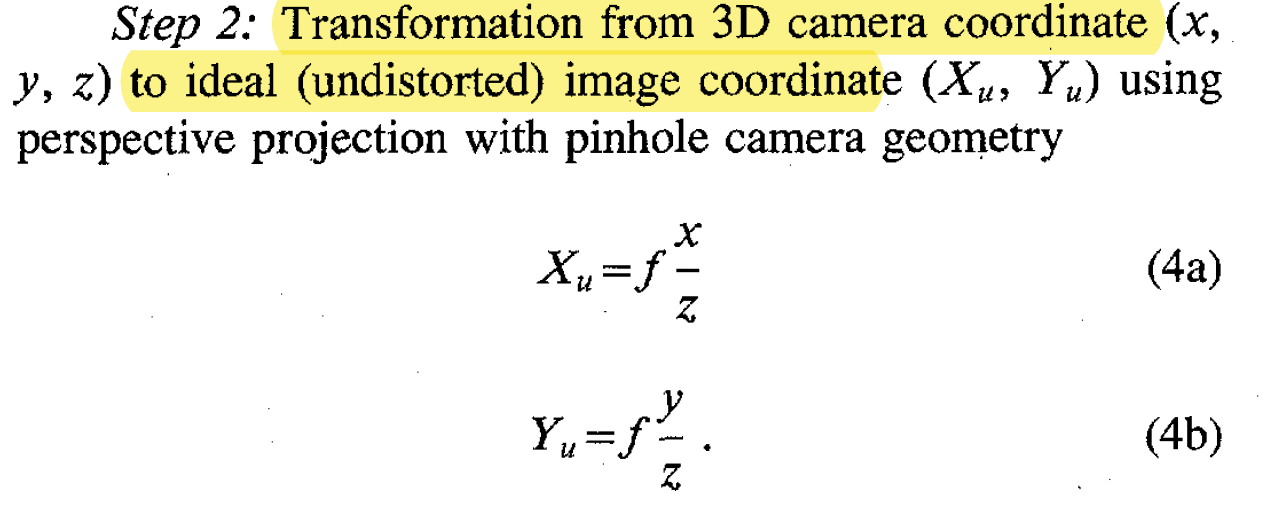

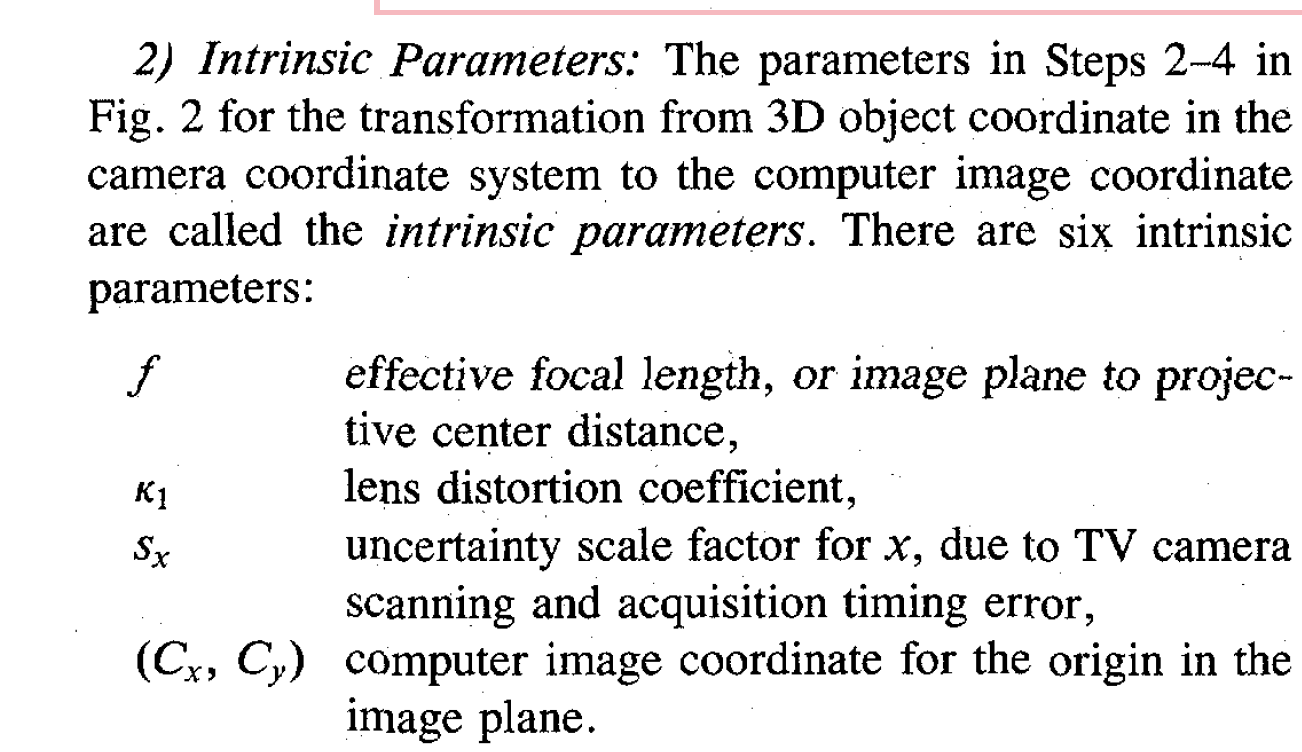

params.Intrinsic

ans = struct with fields:
     focalAttribute: 546.7110
    kappa1Attribute: 3.0531e-07
        cxAttribute: 480
        cyAttribute: 270
        sxAttribute: 1.0007


f=params.Intrinsic.focalAttribute
x_u=f*(x/z)
y_u=f*(y/z)
coord_image_ideal=[x_u;y_u]

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

f = 546.7110

**2D ideal image coordinate to 2D distorted image coordinate**

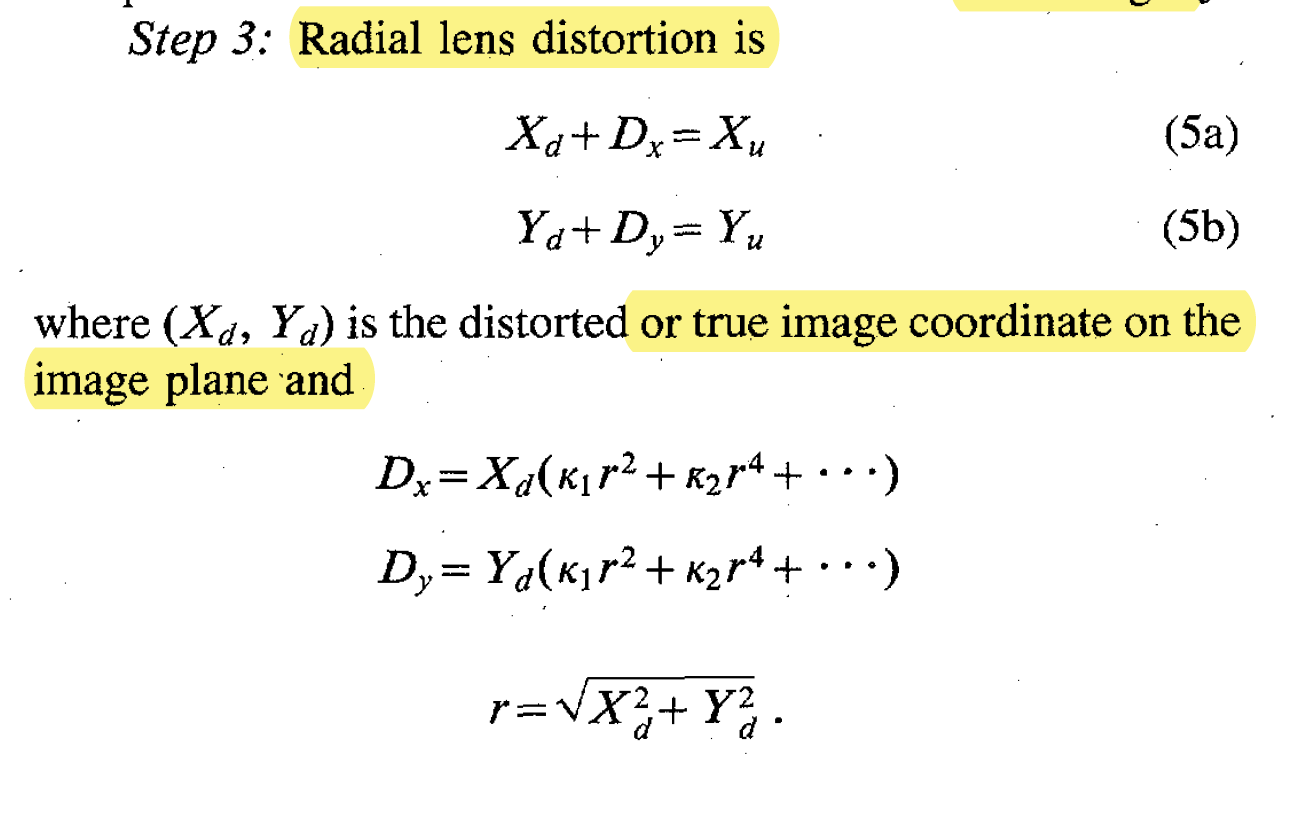


$$\begin{array}{l}
x_u =x_d \left(1+\kappa r^2 \right)\\
y_u =y_d \left(1+{\kappa r}^2 \right)\\
r=\sqrt{x_d^2 +y_{d^2 } }
\end{array}$$


k1=params.Intrinsic.kappa1Attribute

k1 = 3.0531e-07

% j'ai aucune idéeeee mdr
% x_d=x_u
% y_d=y_u

r_u= x_u^2 + y_u^2;

r_d=roots([k1^2 k1 1 -r_u]);
r_d=r_d(imag(r_d)==0)

r_d = 1.2967e+04


x_d= (r_d*x_u)/r_u

x_d = 71.9660

y_d= (r_d*y_u)/r_u

y_d = 87.9579


% r_u2= x_u^2+y_u^2;
% x_d=x_u*(1+k1*r_u2);
% y_d=y_u*(1+k1*r_u2);
% 
% r_d2=x_d^2+y_d^2
% x_d=x_u*(1+k1*r_d2)
% y_d=x_d*(1+k1*r_d2)

**2D distorted image coordinate to computer image coordinates**

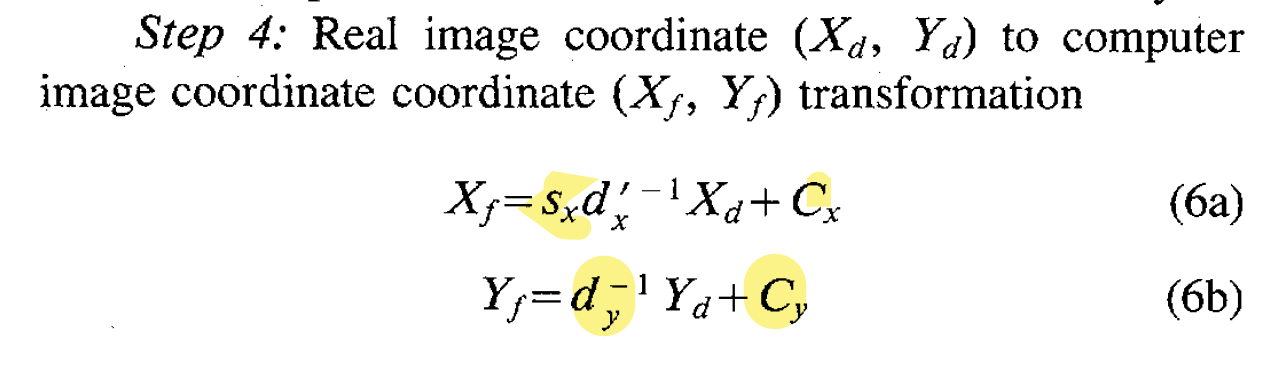

params.Intrinsic

ans = struct with fields:
     focalAttribute: 546.7110
    kappa1Attribute: 3.0531e-07
        cxAttribute: 480
        cyAttribute: 270
        sxAttribute: 1.0007


sx=params.Intrinsic.sxAttribute

sx = 1.0007

Cx=params.Intrinsic.cxAttribute

Cx = 480

Cy=params.Intrinsic.cyAttribute

Cy = 270

params.Geometry

ans = struct with fields:
     widthAttribute: 960
    heightAttribute: 540
       ncxAttribute: 960
       nfxAttribute: 960
        dxAttribute: 1
        dyAttribute: 1
       dpxAttribute: 1
       dpyAttribute: 1


dx=params.Geometry.dxAttribute

dx = 1

dy=params.Geometry.dyAttribute

dy = 1

ncx=params.Geometry.ncxAttribute

ncx = 960

nfx=params.Geometry.nfxAttribute

nfx = 960


dx=dx*(ncx/nfx);
x_f=((sx*x_d)/dx)+Cx;

x_f = 552.0185

y_f=(y_d/dy)+Cy;

y_f = 357.9579

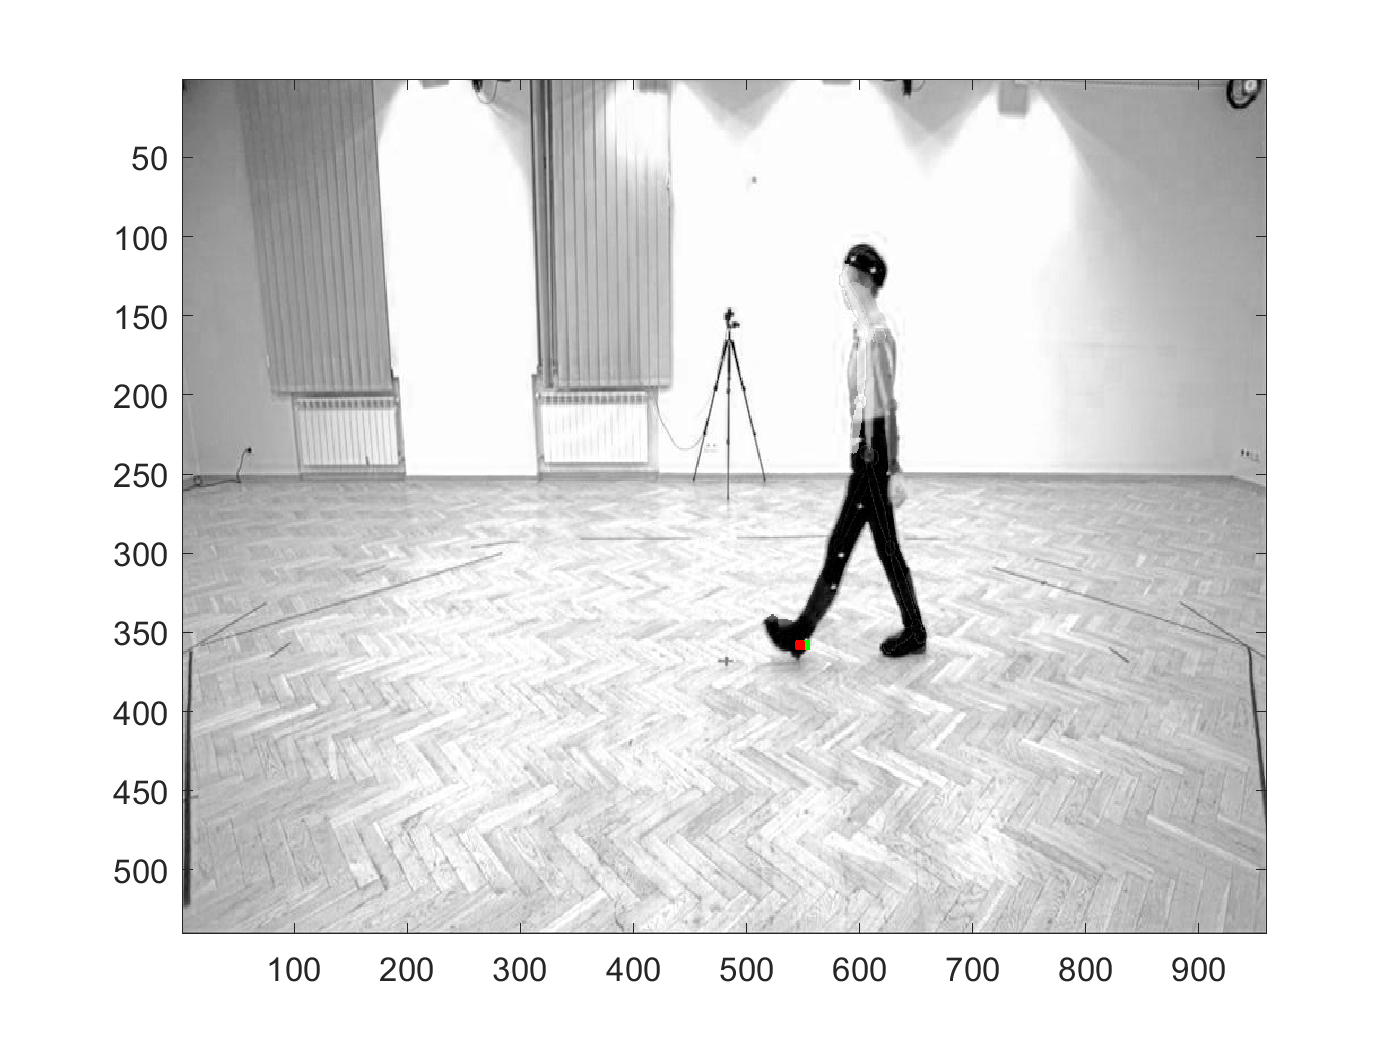

vid = VideoReader('vid_out_colab.avi');
videoFrame = read(vid,n);
img = videoFrame(:,:,1);
imagesc(img);
colormap(gray);
hold on;
r = 1; % r is the radius of the plotting circle
j=0:.01:2*pi; %to make the plotting circle
plot(r*sin(j)+x_f,r*cos(j)+y_f,'.g');
plot(r*sin(j)+op_keypoint(1),r*cos(j)+op_keypoint(2),'.r');
hold off;